# Hour power 2

### List of good data for each channel

Channel 1 and channel 2

48 hour days - currently excluding 48 hour data

%channel 1
goodkgidx1 = [1 2 54 6 7 8 101 10 11 12 14 15 16 19 27 31 100 28 30 33 35 36 37 38 39 40 41 42 54 56];

    for j = 1:length(goodkgidx1)
      gk1(j).trial1 = KatieTrialTrendDessembler(kg(goodkgidx1(j)), 1, goodkgidx1(j));
    end
    
% fortyeightidx1 = [3 4 5 44];
% fortyeightidx2 = [3 4 5 44 45];



    for j = length(gk1):-1:1
        for jj = 1:length(gk1(j).trial1)
       [gk1(j).freq1(jj), gk1(j).pwr1(jj)] = k_welches(gk1(j).trial1(jj), gk1(j).trial1(jj).ld, 10);
       gk1(j).hour1(jj) = gk1(j).trial1(jj).ld;
        end
    end
    

    
    for j = 1:length(goodkgidx1)
      rgk1(j).trial1 = KatieTrialDessembler(kg(goodkgidx1(j)), 1, goodkgidx1(j));
    end

Output argument "out" (and maybe others) not assigned during call to "KatieTrialDessembler".

    
    for j = length(rgk1):-1:1
        for jj = 1:length(rgk1(j).trial1)
       [rgk1(j).freq1(jj), rgk1(j).pwr1(jj)] = k_welches(rgk1(j).trial1(jj), rgk1(j).trial1(jj).ld, 10);
       rgk1(j).hour1(jj) = rgk1(j).trial1(jj).ld;
        end
    end



%channel 2
goodkgidx2 = [1 55 6 7 10 11 12 14 15 16 19 30 31 28 33 35 36 37 38 39 40 41 42 47 98 55 57 97];

    for j = 1:length(goodkgidx2)
      gk2(j).trial2 = KatieTrialTrendDessembler(kg(goodkgidx2(j)), 2, goodkgidx2(j));
    end
    
    for j = length(gk2):-1:1
        for jj = 1:length(gk2(j).trial2)
       [gk2(j).freq2(jj), gk2(j).pwr2(jj)] = k_welches(gk2(j).trial2(jj), gk2(j).trial2(jj).ld, 10);
       gk2(j).hour2(jj) = gk2(j).trial2(jj).ld;
        end
    end
    
    
    for j = 1:length(goodkgidx2)
      rgk2(j).trial2 = KatieTrialDessembler(kg(goodkgidx2(j)), 2, goodkgidx2(j));
    end
    
    for j = length(rgk2):-1:1
        for jj = 1:length(rgk2(j).trial2)
       [rgk2(j).freq2(jj), rgk2(j).pwr2(jj)] = k_welches(rgk2(j).trial2(jj), rgk2(j).trial2(jj).ld, 10);
       rgk2(j).hour2(jj) = rgk2(j).trial2(jj).ld;
        end
    end

# Plots

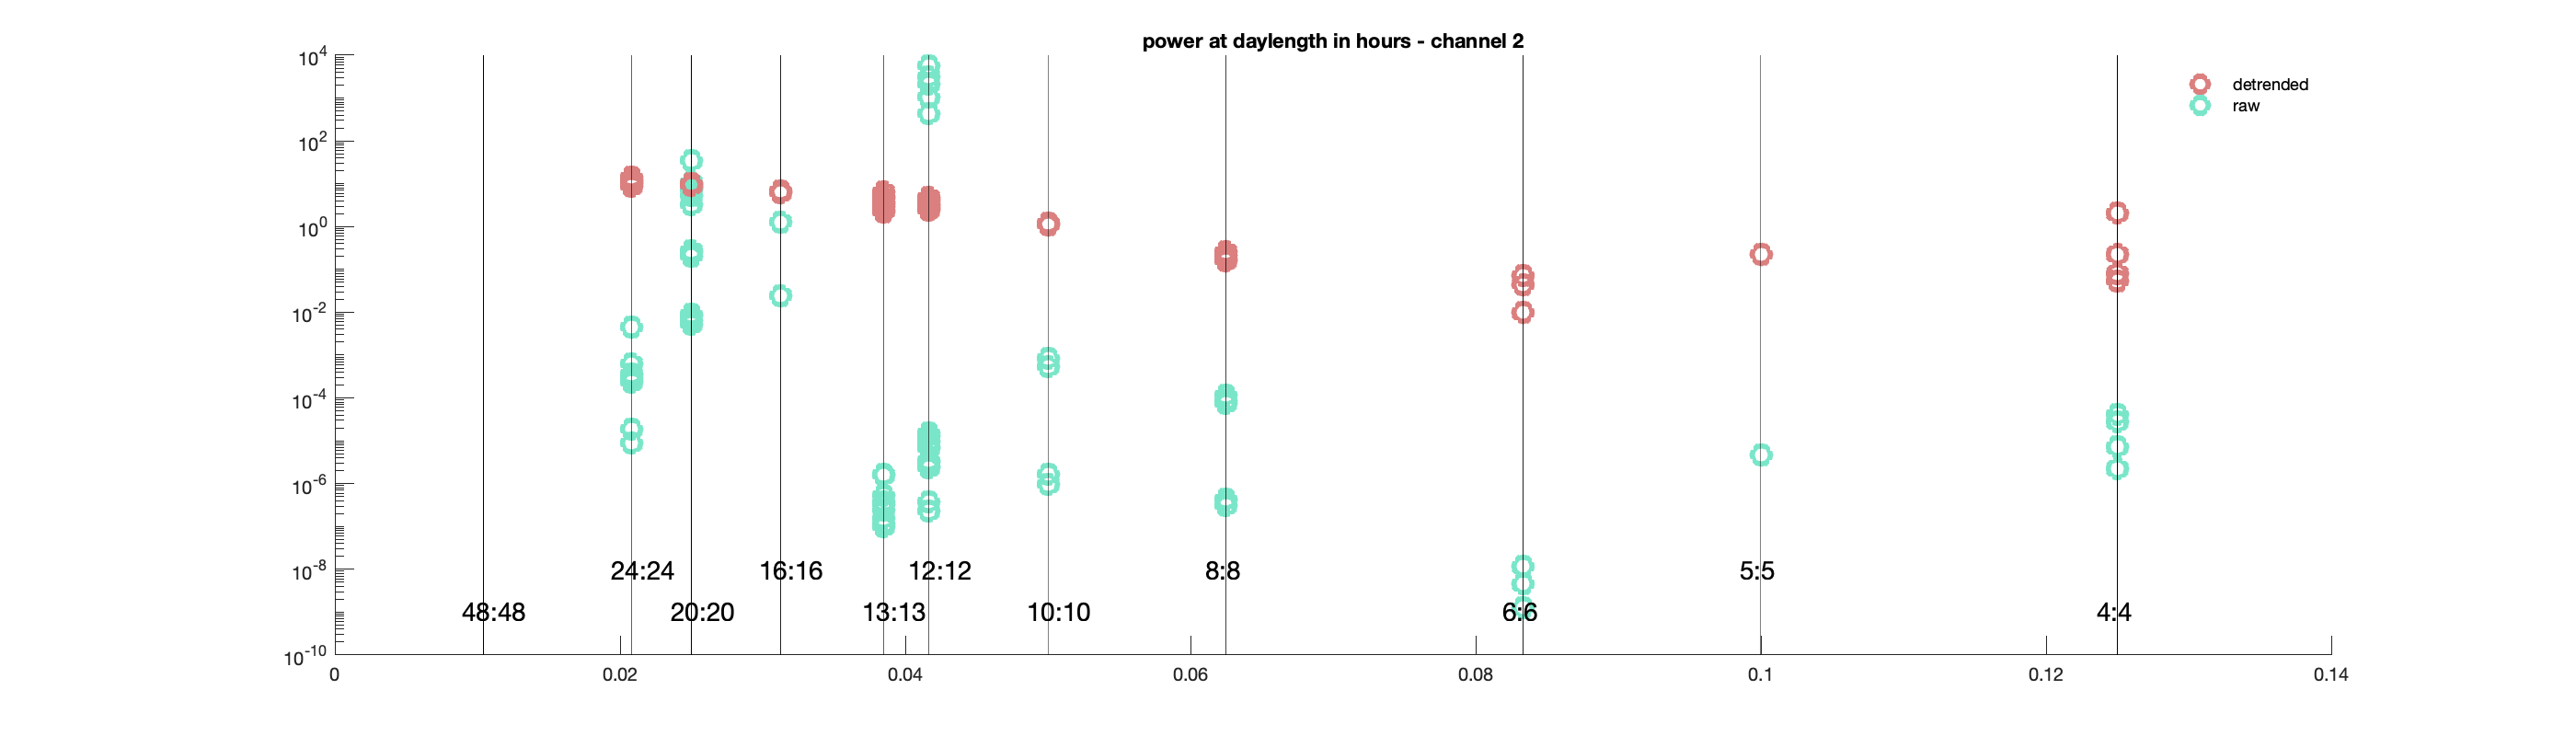

%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

close all; figure(1); clf; hold on; title('power at daylength in hours - channel 2');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

    
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    %plot data on log scale
    %fftmachine
    
   
    for j = 1:length(gk2)
        for jj = 1:length(gk2(j).freq2)
            plot(gk2(j).freq2(jj), gk2(j).pwr2(jj), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3); hold on;
            plot(rgk2(j).freq2(jj),rgk2(j).pwr2(jj), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); hold on;
        end
    end
        set(gca,'yscale', 'log');  
        legend('detrended','raw', 'AutoUpdate','off');
        legend('boxoff')
        
        minY = min(ylim);
        maxY = max(ylim);
        for j=1:length(hrs)

            plot([1/hrs(j), 1/hrs(j)], ylim, 'k-', 'LineWidth', 0.25);
            
            label = num2str(hrs(j)/2);
            str = " " + label + ":" + label;
            
            if mod(j, 2) == 0 % j is even
                pos(j) = minY+ 0.00000001;
            else % j is odd
                pos(j) = minY + 0.000000001;
            end
            text(1/hrs(j)-0.002, pos(j), str, 'FontSize', 14);

        end

%               legend('Ch2','Ch1', 'AutoUpdate','off');
%               legend('boxoff')
       

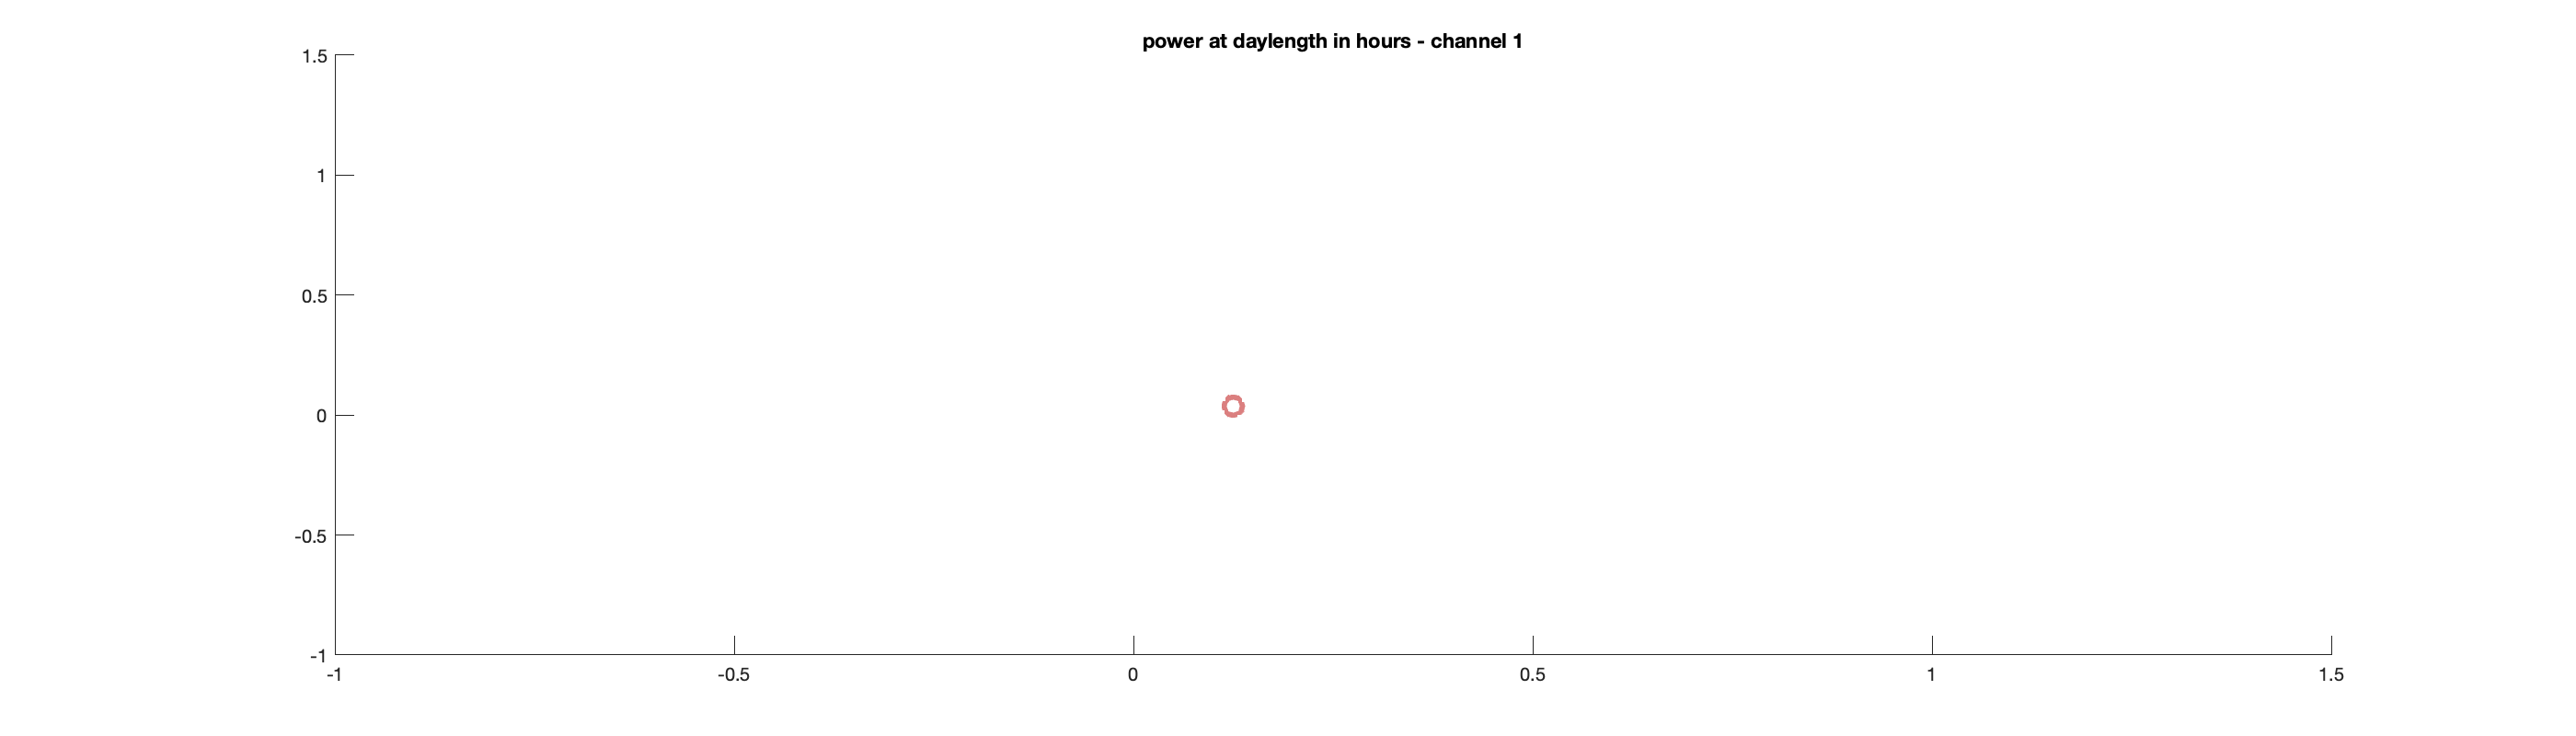

Unrecognized function or variable 'rgk1'.

%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

close all; figure(2); clf; hold on; title('power at daylength in hours - channel 1');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

   
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    
    for k = 1:length(gk1)
        for kk = 1:length(gk1(k).freq1)
          plot(gk1(k).freq1(kk), gk1(k).pwr1(kk), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3);  %ylim([minY, maxY + 0.01]);
          plot(rgk1(k).freq1(kk), rgk1(k).pwr1(kk), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); 
        end      
        
    end         

    
  set(gca,'yscale', 'log');
   legend('detrended','raw', 'AutoUpdate','off');
        legend('boxoff')
        
        minY = min(ylim);
        maxY = max(ylim);
        
        for j=1:length(hrs)

            plot([1/hrs(j), 1/hrs(j)], ylim, 'k-', 'LineWidth', 0.25);
            label = num2str(hrs(j)/2);
            str = " " + label + ":" + label;
            if mod(j, 2) == 0 % j is even
                pos(j) = minY + 70;
            else % j is odd
                pos(j) = minY + 30 ;
            end
            text(1/hrs(j)-0.002, pos(j), str, 'FontSize', 14);

        end
              

